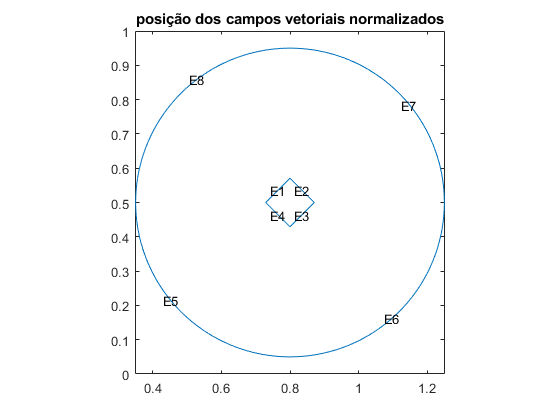

% calculo do campo EM espalhado ao redor de uma nanopartícula quadrada
numberOfPDE = 1;
model = createpde(numberOfPDE);
g = @scatterg;
k = 100;
c = 1;
a = -k^2;
f = 0;
geometryFromEdges(model,g);
figure; 
pdegplot(model,'EdgeLabels','on'); 
axis equal
title 'Geometry with Edge Labels Displayed';
ylim([0,1])

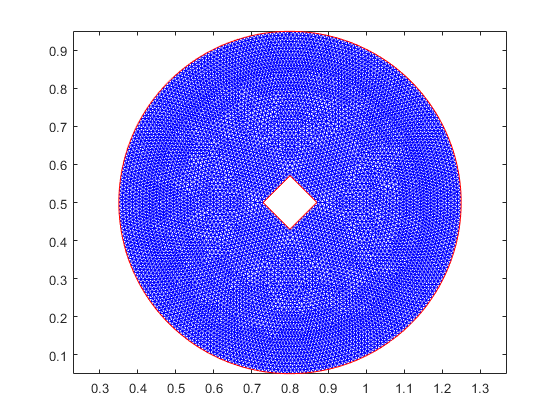

bOuter = applyBoundaryCondition(model,'neumann','Edge',(5:8),'g',0,'q',-60i);
innerBCFunc = @(loc,state)-exp(-1i*k*loc.x);
bInner = applyBoundaryCondition(model,'dirichlet','Edge',(1:4),'u',innerBCFunc);
specifyCoefficients(model,'m',0,'d',0,'c',c,'a',a,'f',f);
generateMesh(model,'Hmax',0.001);
figure
pdemesh(model); 
axis equal

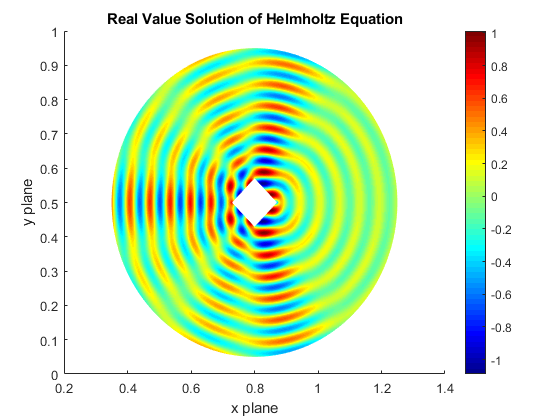

result = solvepde(model);
u = result.NodalSolution;
figure
pdeplot(model,'XYData',real(u),'Mesh','off');
colormap(jet)
xlabel 'x plane'
ylabel 'y plane'
title('Real Value Solution of Helmholtz Equation')

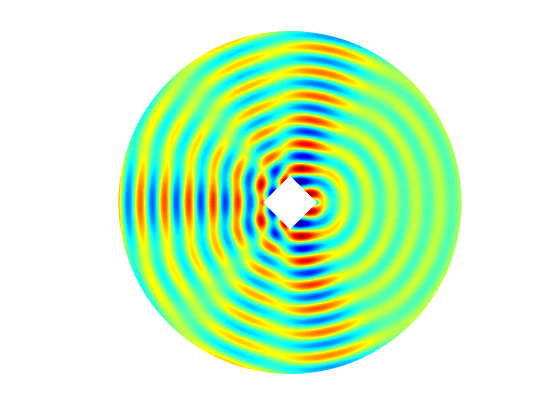

figure
m = 10;
maxu = max(abs(u));
for j = 1:m
    uu = real(exp(-j*2*pi/m*sqrt(-1))*u);
    pdeplot(model,'XYData',uu,'ColorBar','off','Mesh','off');
    colormap(jet)
    caxis([-maxu maxu]);
    axis tight
    ax = gca;
    ax.DataAspectRatio = [1 1 1]; 
    axis off
    M(j) = getframe;
end